# Informe de Laboratorio 1

Para el correcto funcionamineto del siguient codigo se debe adjuntar la base de datos de matlab "Nivel_sensor" adjuntado al buzón.

## Pregunta 1

Realice una explicación sintética y con apoyo gráfico de la planta de nivel, sus partes y funcionalidades generales.

**Respuesta**:

Para el desarrollo de esta práctica, se empleará una planta de control digital suministrada por la empresa Make Solutions, ubicada en el segundo piso del bloque de ingeniería.

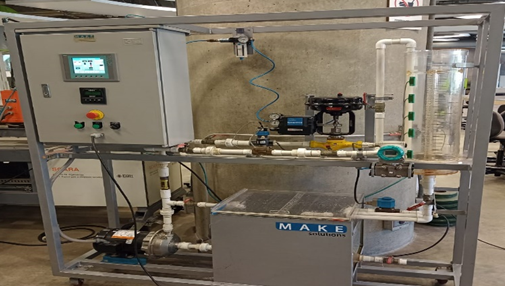

Figura 1. Planta de Control Digital

La planta se compone de varias partes, cada una desempeñando una función crucial para el funcionamiento y control efectivo del sistema. El panel de control central (ver Figura 2) actúa como el cerebro de la operación, compuesto por una pantalla de la marca Siemens y botones de control, incluyendo apagado, inicio y control externo. Para llevar a cabo la práctica, se utilizará el control remoto desde un ordenador con el software Simulink para controlar la planta y realizar las actividades requeridas.

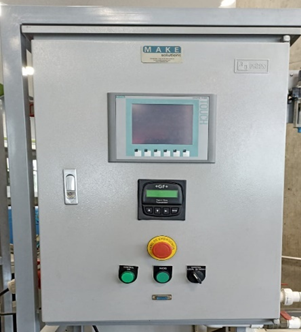

Figura 2. Panel Digital

El principal actuador del sistema es una motobomba, encargada de bombear el líquido a través del sistema. Es esencial para regular el caudal del sistema, siendo una de las áreas de estudio en el laboratorio la variación de la velocidad de la motobomba. Otro componente clave es el tanque de almacenamiento del líquido, junto con la válvula de vaciado que controla la velocidad de vaciado del tanque, fundamental para simular un sistema de primer orden.

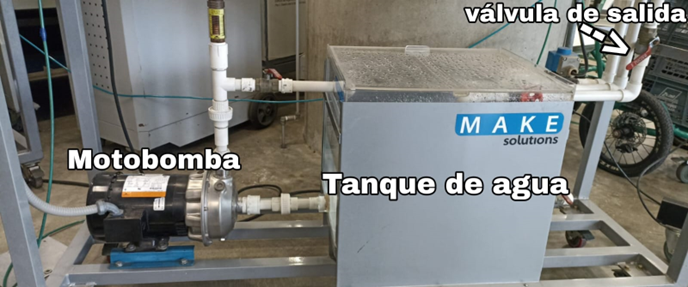

Figura 3. Parte Inferior de la Planta

En la parte superior de la planta, se encuentra una electroválvula controlada desde el equipo remoto, que regula el caudal que ingresa al tanque de nivel. Seguido por el tanque de nivel o tanque de llenado, donde se deposita el líquido y se controla la altura del mismo.

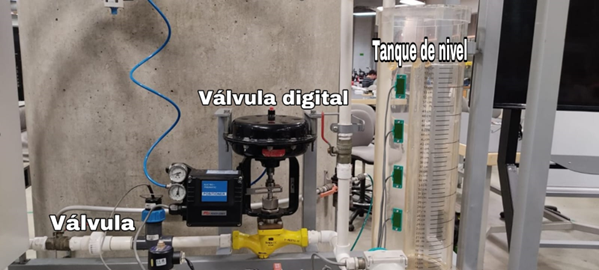

Figura 4. Parte Superior de la Planta

En las paredes del tanque, se encuentran sensores que forman parte del sensor de nivel. Estos sensores indican la altura del líquido mediante un voltaje, donde un voltaje mayor representa una altura mayor del líquido. El sensor de nivel utilizado es el modelo 7MF4433.

## Pregunta 2

Tras consultar las características del procesador del PLC de la planta y de la tarjeta de adquisición de datos extraiga las principales características del microcontrolador o microprocesador de ambos dispositivos y realice una tabla comparativa (procesador, arquitectura del procesador, conjunto de comandos usados, velocidad del procesador, forma de representación de los números decimales, memoria ROM, memoria RAM, velocidad del ADC, tecnología usada para el ADC y buses de comunicación).

**Respuesta**:

Después de llevar a cabo la consulta correspondiente, se ha identificado la referencia del PLC utilizado dentro de la planta, así como la DAQ empleada en la práctica. A fin de apreciar las características de ambos dispositivos, se presenta la siguiente tabla comparativa. El PLC corresponde al modelo S7-1200, mientras que la DAQ es una National Instruments USB-6009.

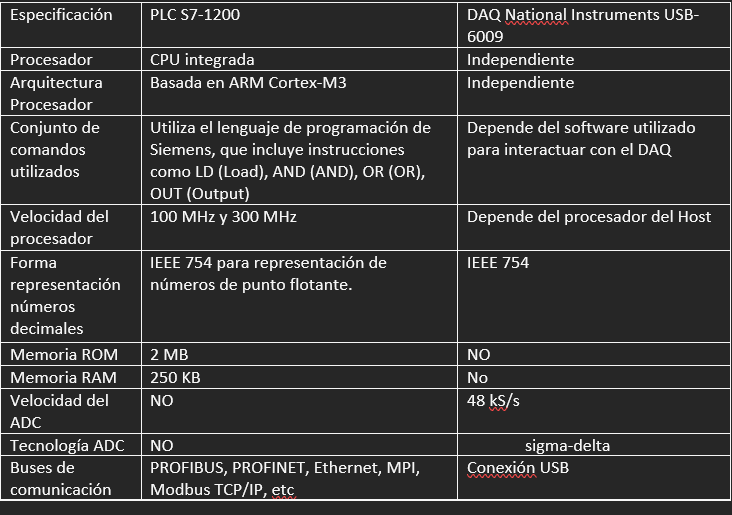

Tabla 1. Especificaciones técnicas componentes 

Se puede apreciar una clara diferencia en el propósito final de cada dispositivo mientras que un PLC se centra en el control y la automatización de procesos industriales, una DAQ se utiliza para adquirir datos de sensores y dispositivos de medición en una amplia variedad de aplicaciones, con enfoque en la adquisición y procesamiento de datos en tiempo real

## Pregunta 3

Tras consultar las características del sensor de nivel, genere una corta explicación de sus características y funcionalidad.

**Respuesta**:

## Caracterizacion sensor de nivel

El transmisor para presión absoluta, DS series (Smart) 7MF4232, usado en la práctica y mostrado en la figura 1, tiene como función medir el nivel de líquido de la planta. Se realiza mediante la presión que una columna de fluido de altura  ejerce sobre una membrana separadora de acero inoxidable, y usando de intermediario un líquido de relleno de aceite de silicona, se transmite la presión a una membrana de medición, modificando así el valor de cuatro piezoresistencias de silicio dispuestas sobre esta y conectadas en puente Wheatstone. Se genera una variación del voltaje de salida proporcional a la presión ejercida, se amplifica y se digitaliza la señal para luego ser enviada a un microprocesador que corregirá su linealidad y variaciones respecto a la temperatura, posteriormente será convertida en una señal de corriente de 4 a 20 en un convertidor digital/analógicoEl transmisor para presión absoluta, DS series (Smart) 7MF4232, usado en la práctica y mostrado en la figura 1, tiene como función medir el nivel de líquido de la planta. Se realiza mediante la presión que una columna de fluido de altura  ejerce sobre una membrana separadora de acero inoxidable, y usando de intermediario un líquido de relleno de aceite de silicona, se transmite la presión a una membrana de medición, modificando así el valor de cuatro piezoresistencias de silicio dispuestas sobre esta y conectadas en puente Wheatstone. Se genera una variación del voltaje de salida proporcional a la presión ejercida, se amplifica y se digitaliza la señal para luego ser enviada a un microprocesador que corregirá su linealidad y variaciones respecto a la temperatura, posteriormente será convertida en una señal de corriente de 4 a 20 en un convertidor digital/analógico [1].

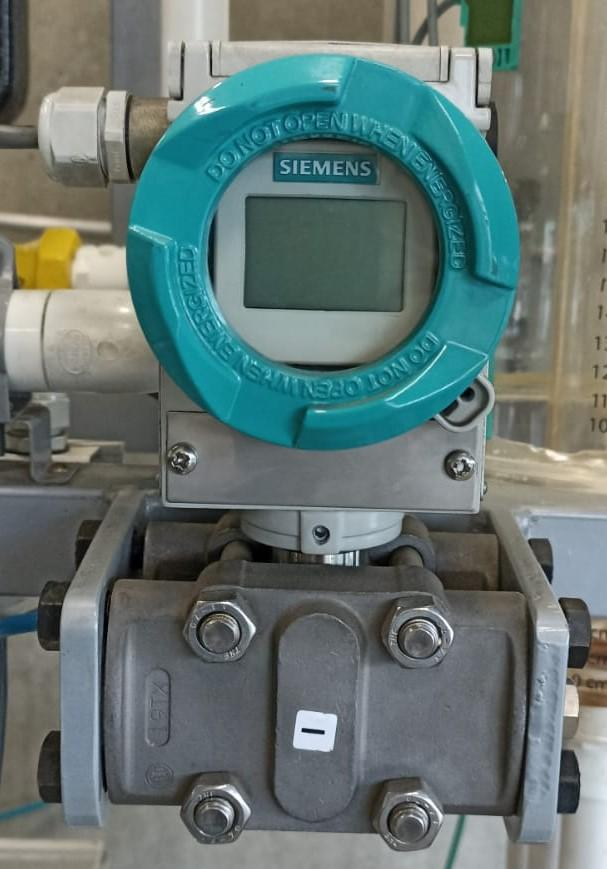

Figura 5: Sensor de nivel

Otras características importantes del sensor se presentan a continuación:

Histéresis:  $\leq$0.1%

Rizado en corriente de salida: de la corriente de salida máxima: $I_{ss} \leq 0.5\%$

Deriva a largo plazo:$\leq$0.2% cada 12 meses para alcance de medida máximo 

Influencia de la temperatura ambiente (-10 °C a 60 °C):  $\leq$1% [1]

## Pregunta 4

Plasme en el informe un gráfico comparativo de los datos obtenidos en la caracterización del sensor para la retroalimentación, los estadísticos calculados y la expresión de ajuste alcanzada, teniendo presente que en el eje de abscisas se debe observar el voltaje y en el de ordenadas el nivel del agua en el tanque ya sea en porcentaje o centímetros, obteniendo y reportando una conclusión sobre las principales características del sensor, con base en el conocimiento adquirido en cursos previos. 

**Respuesta:**

Acontinuación, se planteara el procedimiento y analisis llevado a cabo en la caracterizacion del sensor de presion. 

Se tomaron datos de voltaje para diferentes alturas de liquido cada 2 cm, a continuacion se reportan los resultados obtenidos en la figura 2, y la respectiva función de ajuste. 

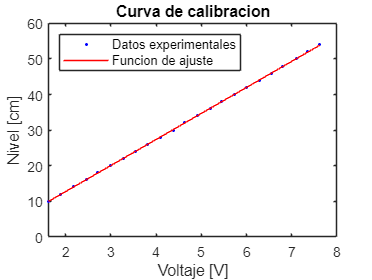

%Sensor de nivel%


Nivel = [54;52;50;48;46;44;42;40;38;36;34;32;30;28;26;24;22;20;18;16;14;12;10];
Voltaje = [7.62;7.35;7.1;6.8;6.55;6.28;6;5.73;5.45;5.2;4.91;4.63;4.38;4.1;3.82;3.55;3.27;2.98;2.7;2.45;2.18;1.88;1.62];
F = fit(Voltaje,Nivel,"poly1");

figure(2)
plot(F,Voltaje,Nivel)
title("Curva de calibracion")
xlabel("Voltaje [V]")
ylabel("Nivel [cm]")
legend({'Datos experimentales','Funcion de ajuste'},'Location','northwest')


disp(F)

     Linear model Poly1:
     F(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       7.319  (7.297, 7.342)
       p2 =      -1.907  (-2.018, -1.796)


## Pregunta 5

*Reporte la modificación del programa base de Simulink para la obtención de mediciones en función del nivel del tanque y con base en las constantes alcanzadas en el numeral anterior. Plasme en la misma diapositiva un gráfico comparativo de los datos obtenidos para la respuesta temporal de la planta ante el escalón unitario generado por la velocidad de la motobomba asignada a cada grupo de trabajo, sus estadísticos, análisis y conclusiones, especialmente respecto al comportamiento dinámico de la planta.*

**Respuesta:**

En Simulink realizó un cambio en las constantes de sensor de presión. La pendiente es de 7,3192 cm/voltaje y el incercepto es de -1.907 cm.

El siguiente gráfico se crea a partir de tomar 63258 datos de nivel (cm) con respecto a una matriz del mismo tamaño en el tiempo.

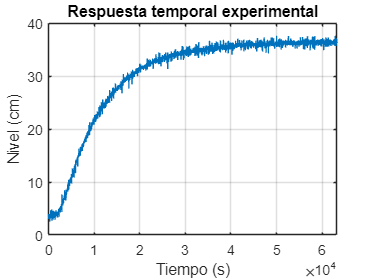

Tiempo=[0:1:63257]';
plot(Tiempo,Nivel_sensor);
title('Respuesta temporal experimental');
xlabel('Tiempo (s)');
ylabel('Nivel (cm)');
grid on;

Notamos que existe un offset en la respuesta escalón. Esto es debido a una "altura muerta" que no se pudo medir con presición debido a la planta. Por otro lado para le elimina el ruido de la respuesta experimental para poder comparar mejor las diferentes respuestas. 

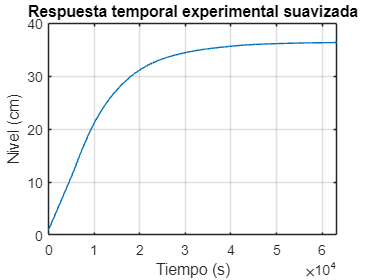

Nivel_suave=smoothdata(Nivel_sensor,'lowess');
plot(Tiempo,Nivel_suave)
title('Respuesta temporal experimental suavizada');
xlabel('Tiempo (s)');
ylabel('Nivel (cm)');
grid on;

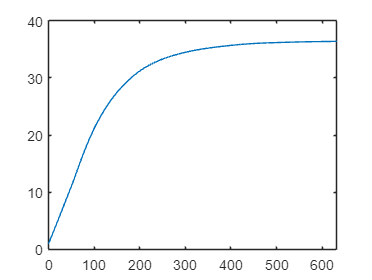

%% Remuestro el función de 63258 datos da 36.
Nivel_indice=round(linspace(1,numel(Nivel_suave),600));
Tiempo_indice=round(linspace(1,numel(Tiempo),600));
Nivel_remuestreado=Nivel_suave(Nivel_indice);
%%% función resultante
Tiempo_remuestreado=Tiempo(Tiempo_indice)/(100);
f_exp=plot(Tiempo_remuestreado,Nivel_remuestreado);

title('Respuesta temporal generado por datos remuestreada');
xlabel('Tiempo (s)');
ylabel('Nivel (cm)');
grid on;

## Pregunta 6

*Plasme el procedimiento de obtención y resultado del modelo teórico de la planta de nivel, con base en la realización de las tareas comunicadas en las clases magistrales y donde se observe el logro de una función de transferencia, con constantes numéricas gracias a los datos medidos en la planta de nivel. *

**Respuesta:**

Para modelar un dispositivo de almacenamiento de agua que experimenta variaciones en su flujo másico, derivadas de los ductos de entrada y salida del líquido se utiliza la ley de conservación de la materia:

syms q_i q_o A dt h dh h(t) Q_i(s) Q_o(s) K_teo H(s) G(s) a K r_2 r_1; 
A*(dh/dt)==q_o-q_i

Donde A es el area transversal del tanque, dh/dt es la razón de cambio de la altura, q_i s el flujo de entrada y q_o es el flujo de salida. 

Luego q_0 esta dado por:

q_o=h*a;

Donde h es la altura y a les la frecuencia

q_i-h(t)==A*(dh/dt)

$$ans = q_{i}-h\left(t\right)=\frac{A\,\mathrm{dh}}{\mathrm{dt}}$$

Como el el contenedor es cilindrico entonces:

A==pi*(r_1^2-r_2^2)

$$ans = A=\pi \,\left({r_{1}}^{2}-{r_{2}}^{2}\right)$$

Luego reemplazando:

pi*(r_1^2-r_2^2)*(dh/dt)==q_i-(h*a)

$$ans(t) = \frac{\pi \,\mathrm{dh}\,\left({r_{1}}^{2}-{r_{2}}^{2}\right)}{\mathrm{dt}}=q_{i}-a\,h\left(t\right)$$

Aplicando la transformada de Laplace, reorganizando y reemplazando t=pi*(r_1^2-r_2^2) entonces:

H(s)/Q_i(s)==1/(t*s+a)

$$ans = \frac{H\left(s\right)}{Q_{i}\left(s\right)}=\frac{1}{a+s\,t}$$

En terminos de el caudal de entrada y salida tenemos:

Q_o(s)/Q_i(s)==K_teo/(t*s+1)

$$ans = \frac{Q_{o}\left(s\right)}{Q_{i}\left(s\right)}=\frac{K_{\mathrm{teo}}}{s\,t+1}$$

Donde K=A*a. Area es 0.0336 a=1085.4836

s=tf('s');
K_teo=36.48;
G_teo=K_teo/(Tiempo_muerto*s+1)

G_teo =
 
    36.48
  ----------
  21.2 s + 1
 
Continuous-time transfer function.
Model Properties


## Pregunta 7

*Plasme, con base en otra de las tareas, en qué consiste la aproximación de Padé y su utilidad, así como la expresión final que se lograría de la de su aplicación en la función de transferencia calculada en el numeral anterior y para aproximar el tiempo muerto que se presenta en la planta.*

**Respuesta:**

El tiempo muerto se define como un período en el que un cambio en la variable manipulada no produce efecto observable en la variable de proceso. Se trata de un retraso en la respuesta de control durante el cual el proceso parece estar "muerto".

En este caso el tiempo muerto será el tiempo que tarda el sensor de nivel en empezar a sensar la señal de nivel. 

En este caso el tiempo muerto es aproximadamente 21.2 segundos. 

Tiempo_muerto=21.2;
retraso=exp(-Tiempo_muerto*s);
G2=G_teo*retraso;
G_padeteo=pade(G2,1);

## Pregunta 8

*Consiga con una visualización de los gráficos, y con base en las instrucciones del módulo de CI de PI1, otra función de transferencia a partir de las características de la curva lograda. Por otra parte, obtenga una función de transferencia adicional agregando una aproximación de Padé para el tiempo muerto que se presenta en la dinámica de la planta.*

**Respuesta:**

Para obtener la función experimental se establece la ecuación general de una función de transferencia de primer orden. 

syms K a s
G(s)=K/(a+s)

$$G(s) = \frac{K}{a+s}$$

s =
 
  s
 
Continuous-time transfer function.
Model Properties


Ahora, sabemos que a es la frecuencia al 63% de la planta que se encontro experimentalmente de la siguiente forma:

- Se saca el 63% del nivel máximo del nivel.

- Utilizando un cronómetro se mide el tiempo hasta que llegue al 63% del nivel. 

En ese orden de ideas se sabe que el máximo es 36.4 cm. El 63% de 36.4 es 22.932 cm. El tiempo que tarda en llegar a esa nivel es de 94.97 s. Con estos datos encontramos a

s=tf('s')
Nivel_satura=36.4;
Nivel_63=36.4*0.63;
tiempo_63=94.97;
a=1/tiempo_63;

Luego hallamos la ganancia K, que es el producto de la frecuencia por el nivel maximo. 

K=Nivel_satura*a;

G =
 
    0.3833
  -----------
  s + 0.01053
 
Continuous-time transfer function.
Model Properties


Obtenemos la funcion de transferencia experimental

G=K/(s+a)

Finalmente encontramos la aproximación de Pade experimental. 

G1=G*retraso;
G_pade1=pade(G1,1);

## Pregunta 9

*Consulte en qué consiste el System Identification Toolbox de MATLAB, escribiendo una breve explicación, y obtenga una última función de transferencia haciendo uso del módulo, generando un análisis y unas conclusiones.*

**Respuesta**:

System Identification Toolbox ofrece funciones de MATLAB, bloques de Simulink y una app para modelado de sistemas dinámicos, análisis de series temporales y predicción. Puede aprender relaciones dinámicas entre variables medidas para crear funciones de transferencia, modelos de procesos y modelos de espacio de estados en tiempo continuo o discreto mientras utiliza datos del dominio del tiempo o de la frecuencia.

Se utiliza la función "systemIdentification" para abrir la interfaz, luego en importar data se selecciona "time domain data" para adjuntar la entrada y salida del sistema. Se pone el número de ceros o polos que se espera de la función y se genera la función de transferencia. 

Luego se pone 0.32 que corresponde a la ganancia del motor (32%)

G_ss=0.32*(1.949)/(s+0.0180);

## Pregunta 10

*Complemente la tabla comparativa que se observa a continuación: *

**Respuesta:**

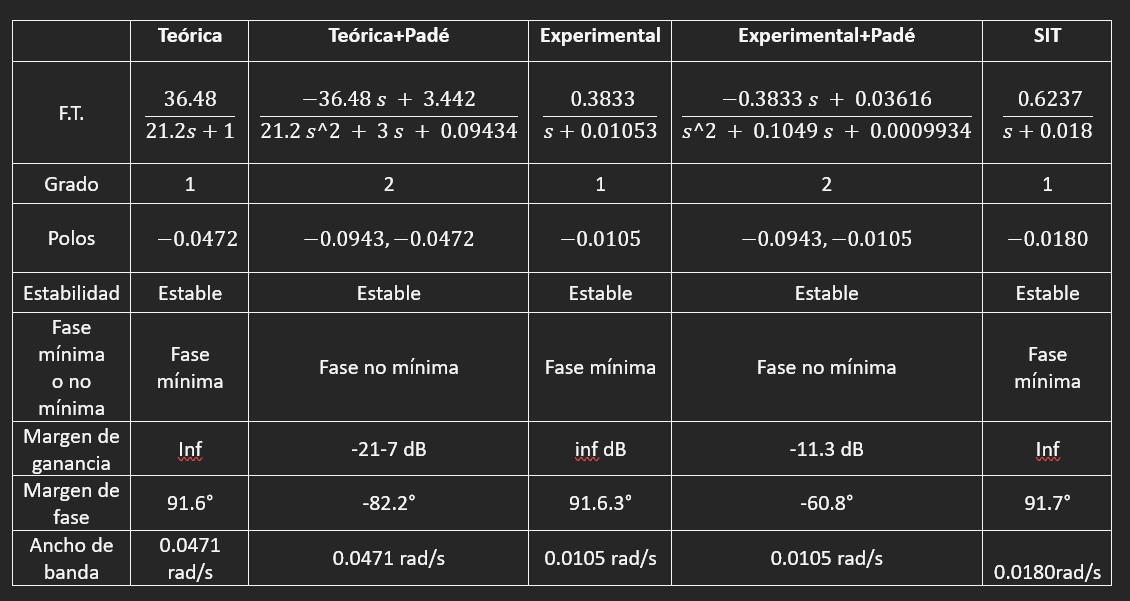

## Pregunta 11

*Genere para las 5 funciones de transferencia obtenidas, un gráfico comparativo superpuesto de la ubicación de los polos y los ceros y otro de la respuesta temporal a un escalón unitario, adhiriendo a este último la respuesta obtenida directamente de la planta. Realice el respectivo análisis y conclusiones.*

**Respuesta**:

Para la respuesta temporal en escalón unitario:

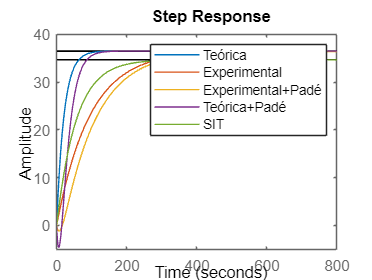

step(G_teo,G,G_pade1,G_padeteo,G_ss)

legend('Teórica', 'Experimental','Experimental+Padé','Teórica+Padé','SIT');

Se puede ver que aunque todas las respuesta en el tiempo tienden a estabilizarse en un mismo punto.

Para los ceros y polos

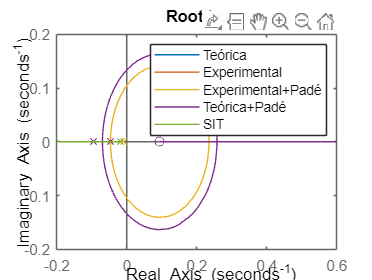

rlocus(G_teo,G,G_pade1,G_padeteo,G_ss)

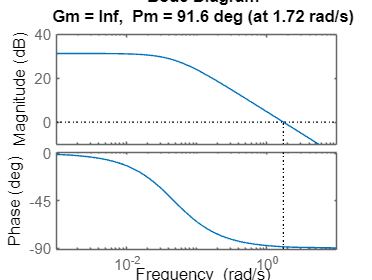

legend('Teórica', 'Experimental','Experimental+Padé','Teórica+Padé','SIT');

Se puede ver claramente como los sistemas de primer orden al ser de fase mínima son estables al esta en el semiplano izquierdo, mientras que las de segundo orden se comportan como sistemas de fase no mínima y se modelan por medio de Nyquist. 

## Pregunta 12

Obtenga un Diagrama de Bode con subventanas (una ventana para cada función de transferencia) para las 5 funciones de transferencia, indicando en cada diagrama el margen de ganancia y de fase. Genere un análisis y unas conclusiones.

**Respuesta**:

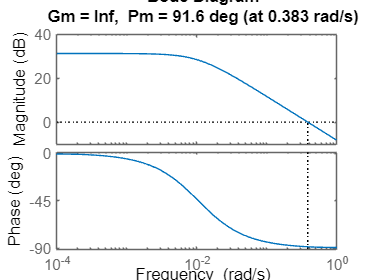

margin(G_teo)

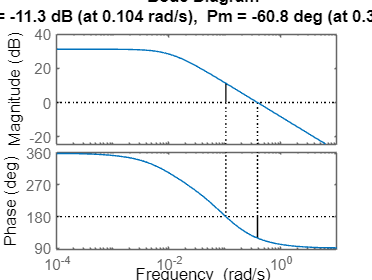

margin(G)

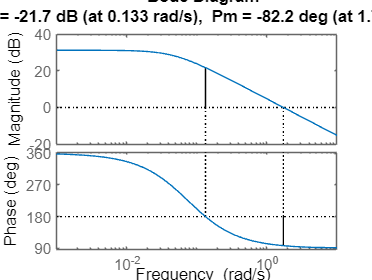

margin(G_pade1)

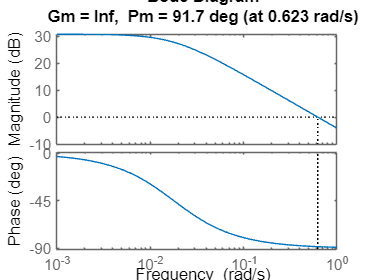

margin(G_padeteo)

margin(G_ss)

Lo anterior nos está diciendo que dependiendo de como modele un sistema, los margenes de ganancia podrán o no estar definidos. 

## Pregunta 13

* Con todos los resultados anteriores, y de manera argumentada, seleccione la función de transferencia que mejor se aproxime al comportamiento de la planta*

**Respuesta:**

Se puede ver claramente que la aproximación+padé es la que mas se acerca a la función. 

## Pregunta 14

*Tras la selección de la mejor función de transferencia en el numeral anterior, discretice la expresión en MATLAB por medio del método impulse, ZOH y 3 adicionales a discreción del grupo de trabajo. Genere los gráficos, comparativas, análisis y conclusiones similares a los llevados a cabo en el numeral 11. *

**Respuesta**

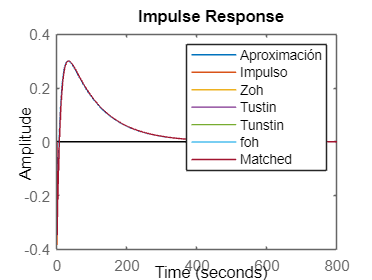

Tiempo_muestreo=1;
Gz1=c2d(G_pade1,Tiempo_muestreo,'impulse');
Gz2=c2d(G_pade1,Tiempo_muestreo,'ZOH');
Gz3=c2d(G_pade1,Tiempo_muestreo,'tustin');
Gz4=c2d(G_pade1,Tiempo_muestreo,'foh');
Gz5=c2d(G_pade1,Tiempo_muestreo,'matched');
impulse(G_pade1, Gz1,Gz2,Gz3,Gz4,Gz4,Gz5)

legend('Aproximación','Impulso', 'Zoh', 'Tustin','Tunstin','foh','Matched')


Podemos concluir de lo anterior es que aunque se tengan diferentes tecnicas de discretización a un periodo de muestreo de 1 segundo po la cantidad de datos en el experimento casi no hay diferencia. 